## Parte I

% Read file data
cal_data = readtable("data/cal.csv");

% Plot scatter data and fit curves
clf; hold on;
scatter(cal_data.Deslocamento__m_, cal_data.Tens_o_V__20_C, "red");
scatter(cal_data.Deslocamento__m_, cal_data.Tens_o_V__30_C, "green");
scatter(cal_data.Deslocamento__m_, cal_data.Tens_o_V__40_C, "blue");

f_20c = fit(cal_data.Deslocamento__m_, cal_data.Tens_o_V__20_C, 'poly1')

f_20c =      Linear model Poly1:
     f_20c(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1304  (0.1289, 0.1319)
       p2 =      -0.002  (-0.011, 0.007001)

f_30c = fit(cal_data.Deslocamento__m_, cal_data.Tens_o_V__30_C, 'poly1')

f_30c =      Linear model Poly1:
     f_30c(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        0.29  (0.2887, 0.2913)
       p2 =       0.002  (-0.005795, 0.009795)

f_40c = fit(cal_data.Deslocamento__m_, cal_data.Tens_o_V__40_C, 'poly1')

f_40c =      Linear model Poly1:
     f_40c(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =        0.47  (0.4687, 0.4713)
       p2 =       0.002  (-0.005795, 0.009795)

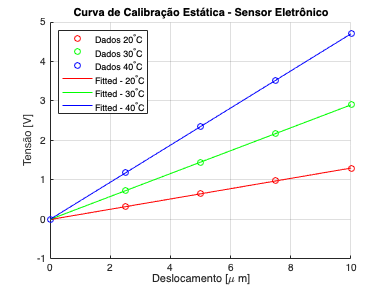


plot(f_20c, "red");
plot(f_30c, "green");
plot(f_40c, "blue");

title('Curva de Calibração Estática - Sensor Eletrônico');
legend('Dados 20^{\circ}C', 'Dados 30^{\circ}C', 'Dados 40^{\circ}C', 'Fitted - 20^{\circ}C', 'Fitted - 30^{\circ}C', 'Fitted - 40^{\circ}C', Location='northwest');
xlabel('Deslocamento [\mu m]'), ylabel('Tensão [V]');
grid on;

% Sensibilidades Estáticas
f_20c.p1

ans = 0.1304

f_30c.p1

ans = 0.2900

f_40c.p1

ans = 0.4700

## Parte II

% Read data file 
measured_values = readtable("data/Data05.csv");
measured_values.Properties.VariableNames = {'Num', 'Tens', 'Temp'}

measured_values = 50×3 table
    Num     Tens      Temp 
    ___    ______    ______

     1     2.4837    33.979
     2     1.8672    37.229
     3     2.7627    37.015
     4     2.8438    39.385
     5     2.1268    37.183
     6     3.2955    34.713
     7     3.2946    36.761
     8     2.6812    33.982
     9     2.8636    35.961
    10     2.7873    35.904
    11     2.6066        36
    12     3.0629    35.364
    13     2.4058     38.19
    14     3.7916    32.252
    15     2.6318    36.856
    16      2.757    37.791



% Uncertantisijsdfjlskdjf 
b_vol = 2e-2

b_vol = 0.0200

b_ter = 5e-2

b_ter = 0.0500


N = height(measured_values)

N = 50

s_Tens = std(measured_values.Tens) ./ sqrt(N)

s_Tens = 0.0690

s_Temp = std(measured_values.Temp) ./ sqrt(N)

s_Temp = 0.2138

b_total = sqrt(b_vol.^2 + b_ter.^2)

b_total = 0.0539

s_total = sqrt(s_Temp.^2 + s_Tens.^2)

s_total = 0.2246


u_total = tinv(0.975, N-1) .* sqrt(b_total.^2 + s_total.^2)

u_total = 0.4642

hold off; clf;
temps = zeros(15,1);
tens  = zeros(15, 1);
desl  = zeros(15, 1);

temps(1:5)  = 20;
temps(6: 10) = 30;
temps(11: 15) = 40;

tens(1:5) = cal_data.Tens_o_V__20_C;
tens(6:10) = cal_data.Tens_o_V__30_C;
tens(11:15) = cal_data.Tens_o_V__40_C;

desl(1:5) = cal_data.Deslocamento__m_;
desl(6:10) = cal_data.Deslocamento__m_;
desl(11:15) = cal_data.Deslocamento__m_;

[temps tens desl]

ans =    20.0000         0         0
   20.0000    0.3200    2.5000
   20.0000    0.6500    5.0000
   20.0000    0.9800    7.5000
   20.0000    1.3000   10.0000
   30.0000         0         0
   30.0000    0.7300    2.5000
   30.0000    1.4500    5.0000
   30.0000    2.1800    7.5000
   30.0000    2.9000   10.0000


stem3(temps, tens, desl), hold on;
F = scatteredInterpolant(tens, temps, desl);
new_point = F(2.7197, 36.1131)

new_point = 7.2738

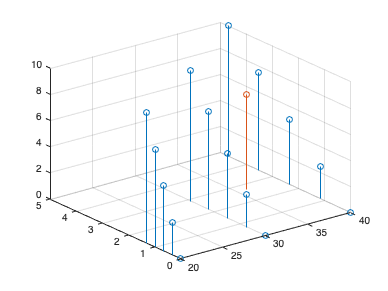

stem3( 36.1131, 2.7197, new_point);